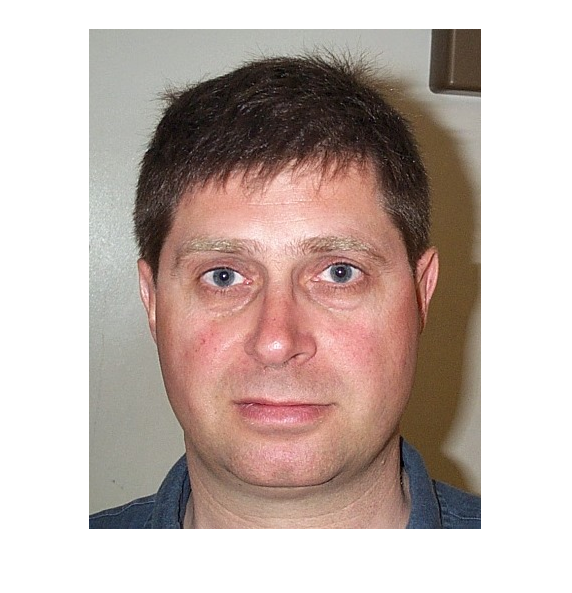

clearvars

inImage = imread('images\DB1\db1_01.jpg');
inImage = im2double(inImage);
originalImage = inImage;
imshow(originalImage);

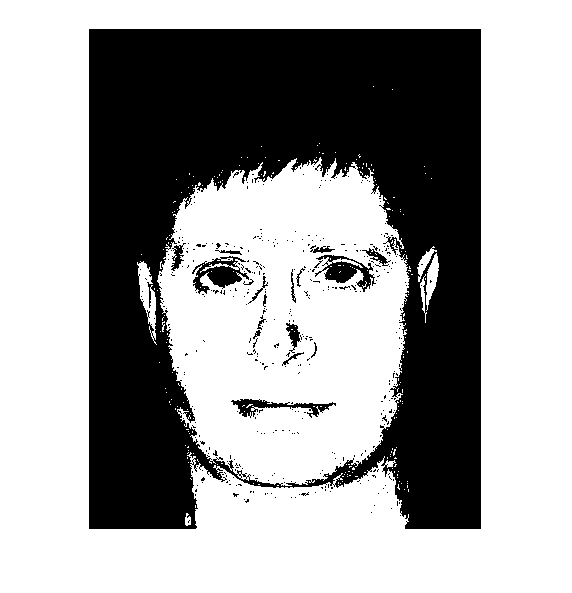

%{
R = inImage(:,:,1);
G = inImage(:,:,2);
B = inImage(:,:,3);
max(R(:))
max(G(:))
max(B(:))

inImage = inImage.*0.7;

imshow(inImage);

inImage = imresize(inImage,0.9);
%imshow(inImage);

x = rand;

if x < 0.5
inImage = imrotate(inImage,5,'bilinear');
imshow(inImage);
disp('+')
else
 inImage = imrotate(inImage,-5,'bilinear');
imshow(inImage);  
disp('-')
end

imwrite(inImage,"images\DB4\db1_16.jpg");

%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%----Automatic White Balancing (AWB)----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inImage = AWB_max(inImage);
%imshow(inImage);
faceMask = skinDetection(inImage);

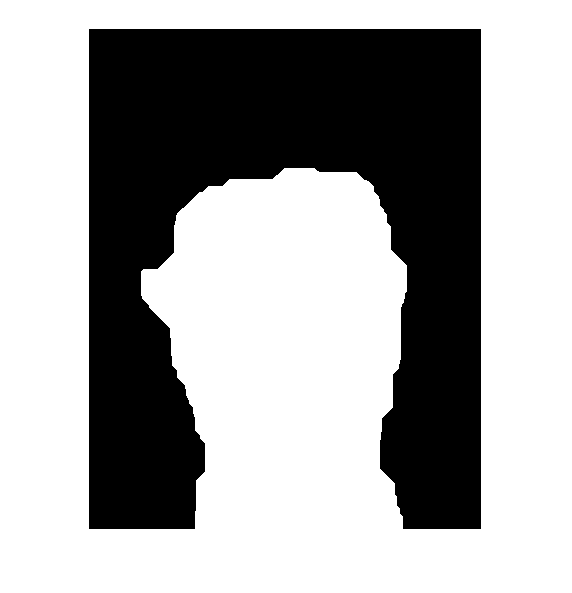

imshow(faceMask);

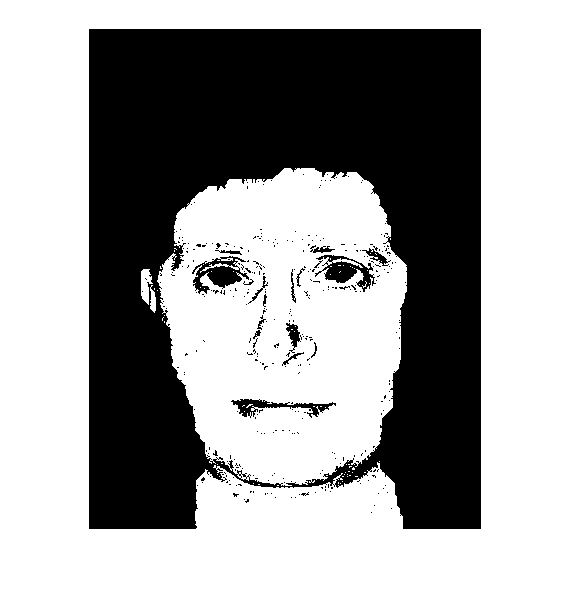


imFace = inImage.*faceMask;
[eye_x, eye_y] = eyedetectionV2(imFace);

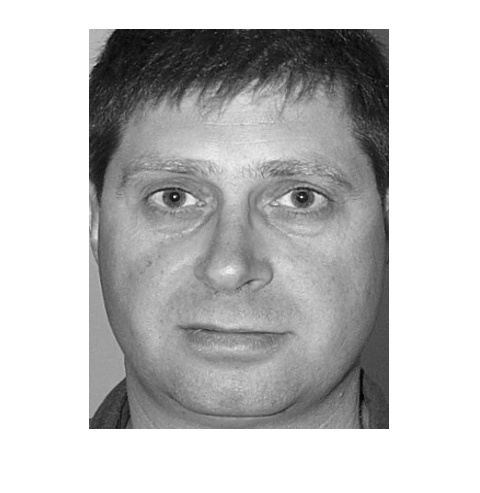

 im = normalizeFace(inImage, [eye_x(1) eye_y(1)],[eye_x(2) eye_y(2)]);
imshow(im);

 %{
imshow(inImage);
axis on
hold on;
row = round(eye1(2));
column = round(eye1(1));

row2 = round(eye2(2));
column2 = round(eye2(1));
plot(column,row, 'r+', 'MarkerSize', 20, 'LineWidth', 2);
plot(column2,row2, 'r+', 'MarkerSize', 20, 'LineWidth', 2);
 %}
%Check result
%C = imfuse(originalImage,mouthMap,'falsecolor','Scaling','independent'); imshow(C)
%imshow(im);

